clear, clc
datadir = 'G:\A_arousal_analysis\data';
% datadir = '/Volumes/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'A_region_predictions.mat'))
load(fullfile(datadir, 'fig_cols.mat'))
cols = cols./255;
cols1 = cols1./255;


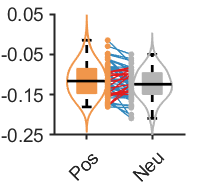

figure;
plot_specificity_box(PAES_VS_pred_pos, PAES_VS_pred_neu, 'colors', cols(1:2,:), 'linecolors',[0.1961    0.5333    0.7412; 0.8902    0.1020    0.1098]);
xticklabels({'Pos','Neu'}); xtickangle(45);
set(gca,'YLim', [-0.25 0.05], 'ytick', -.25:0.1:0.05,'FontName','Helvetica', 'FontSize', 14)

% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 2.3 2.3]);
% print('-dtiff', 'A_PAES_VS.tif', '-r400')


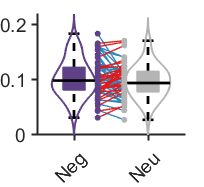

figure;
plot_specificity_box(NAES_VS_pred_neg, NAES_VS_pred_neu, 'colors', cols([3 2],:), 'linecolors',[0.1961    0.5333    0.7412; 0.8902    0.1020    0.1098]);
xticklabels({'Neg','Neu'}); xtickangle(45);
set(gca,'YLim', [0 0.22], 'ytick', 0:0.1:0.2,'FontName','Helvetica', 'FontSize', 14)

% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 2.3 2.3]);
% print('-dtiff', 'A_NAES_VS.tif', '-r400')


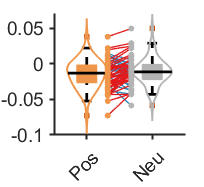

figure;
plot_specificity_box(PAES_dmPFC_pred_pos, PAES_dmPFC_pred_neu, 'colors', cols(1:2,:), 'linecolors',[0.1961    0.5333    0.7412; 0.8902    0.1020    0.1098]);
xticklabels({'Pos','Neu'}); xtickangle(45);
set(gca,'YLim', [-0.1 0.07], 'ytick', -.1:0.05:0.05,'FontName','Helvetica', 'FontSize', 14)

%set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 2.3 2.3]);
% print('-dtiff', 'A_PAES_dmPFC.tif', '-r400')


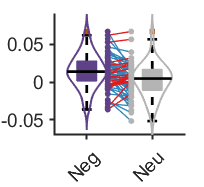

figure;
plot_specificity_box(NAES_dmPFC_pred_neg, NAES_dmPFC_pred_neu, 'colors', cols([3 2],:), 'linecolors',[0.1961    0.5333    0.7412; 0.8902    0.1020    0.1098]);
xticklabels({'Neg','Neu'}); xtickangle(45);
set(gca,'YLim', [-0.07 0.09], 'ytick', -.05:0.05:0.05,'FontName','Helvetica', 'FontSize', 14)

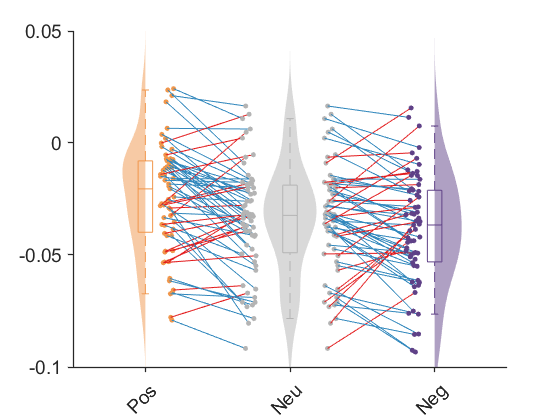

% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 2.3 2.3]);
% print('-dtiff', 'A_NAES_dmPFC.tif', '-r400')


% plot_specificity_box(PAES_dACC_pred_pos, PAES_dACC_pred_neu, 'colors', cols(1:2,:), 'linecolors',[0.1961    0.5333    0.7412; 0.8902    0.1020    0.1098]);
% xticklabels({'Pos','Neu'}); xtickangle(45);
% set(gca,'YLim', [-0.12 0.05], 'ytick', -.1:0.05:0.05,'FontName','Helvetica', 'FontSize', 14)
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 2.3 2.3]);
% print('-dtiff', 'A_PAES_dACC.tif', '-r400')
% 
% plot_specificity_box(NAES_dACC_pred_neg, NAES_dACC_pred_neu, 'colors', cols([3 2],:), 'linecolors',[0.1961    0.5333    0.7412; 0.8902    0.1020    0.1098]);
% xticklabels({'Neg','Neu'}); xtickangle(45);
% set(gca,'YLim', [-0.08 0.12], 'ytick', -.05:0.05:0.1,'FontName','Helvetica', 'FontSize', 14)
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 2.3 2.3]);
% print('-dtiff', 'A_NAES_dACC.tif', '-r400')

dataConditions = {PAES_dACC_pred_pos, PAES_dACC_pred_neu, PAES_dACC_pred_neg};
conditionLabels = {'Pos', 'Neu', 'Neg'};

lefthigher = dataConditions{1} > dataConditions{2};
linecolors{1} = zeros(length(lefthigher), 3);
linecolors{1}(lefthigher, :) = repmat([0.1961    0.5333    0.7412], sum(lefthigher), 1);
linecolors{1}(~lefthigher, :) = repmat([0.8902    0.1020    0.1098], sum(~lefthigher), 1);

lefthigher = dataConditions{2} > dataConditions{3};
linecolors{2} = zeros(length(lefthigher), 3);
linecolors{2}(lefthigher, :) = repmat([0.1961    0.5333    0.7412], sum(lefthigher), 1);
linecolors{2}(~lefthigher, :) = repmat([0.8902    0.1020    0.1098], sum(~lefthigher), 1);

plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 1, 'connectwidth', 0.5, 'colors', cols(1:3,:), 'linecolors',linecolors);
set(gca,'YLim', [-0.1 0.05], 'ytick',-0.1:0.05:0.05, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)
xtickangle(45);

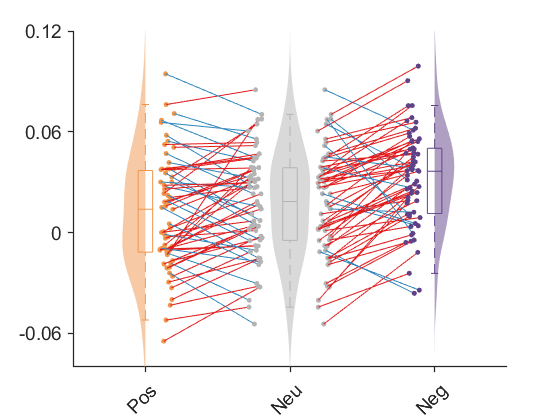

% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 2.5 2.5]);
% print('-dtiff', 'A_PAES_dACC.tif', '-r400')

%%
dataConditions = {NAES_dACC_pred_pos, NAES_dACC_pred_neu, NAES_dACC_pred_neg};
conditionLabels = {'Pos', 'Neu', 'Neg'};

lefthigher = dataConditions{1} > dataConditions{2};
linecolors{1} = zeros(length(lefthigher), 3);
linecolors{1}(lefthigher, :) = repmat([0.1961    0.5333    0.7412], sum(lefthigher), 1);
linecolors{1}(~lefthigher, :) = repmat([0.8902    0.1020    0.1098], sum(~lefthigher), 1);

lefthigher = dataConditions{2} > dataConditions{3};
linecolors{2} = zeros(length(lefthigher), 3);
linecolors{2}(lefthigher, :) = repmat([0.1961    0.5333    0.7412], sum(lefthigher), 1);
linecolors{2}(~lefthigher, :) = repmat([0.8902    0.1020    0.1098], sum(~lefthigher), 1);

plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 1, 'connectwidth', 0.5, 'colors', cols(1:3,:), 'linecolors',linecolors);
set(gca,'YLim', [-0.08 0.12], 'ytick',-0.06:0.06:0.12, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)
xtickangle(45);

% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 2.5 2.5]);
% print('-dtiff', 'A_NAES_dACC.tif', '-r400')